Section 1 - The Normal Distribution

The simple normal distribution is a distribution that is described by 2 variables. The probability density function is given by: $P(x) = \frac{1}{\sigma \sqrt{2 \pi}} \exp \left[ -\frac{(x-\mu)^2}{2 \sigma^2} \right]$ (plotted below). The mean, $\mu$, gives the most likely value in the PDF, while the standard deviation, $\sigma$, describes the spread of the distribution. This is only for a monovariate distribution. For higher dimensional Normal distributions, you need to account for correlations between the different variables. Note that the code below plots the distribution with the mean centered, so adjusting the value of $\mu$ will not appear to move the distribution. 

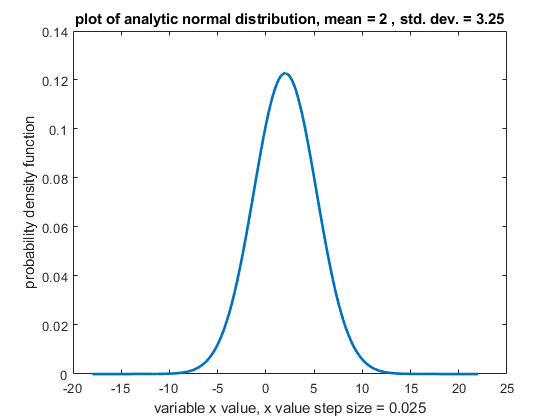

mu =2;
std = 3.25;
xstart = -20;
xstep = .025;
xend = 20;
x = mu+xstart:xstep:mu+xend;
normal_pdf = (1/(std*sqrt(2*pi)))*exp(- (x - mu).^2/(2*std^2));
figure(1)
plot(x,normal_pdf,"LineWidth",2);
title(['plot of analytic normal distribution, mean = ' num2str(mu) ' , std. dev. = ' num2str(std) ])
ylabel('probability density function')
xlabel(['variable x value, x value step size = ' num2str(xstep)])

For calculating the probability of having a value less than or equal to a given value, $x$, pulled from a Normal distribution, we look at the integral of the normal distribution's pdf from $-\infty$ to $x$. Below we use the Matlab function normcdf().

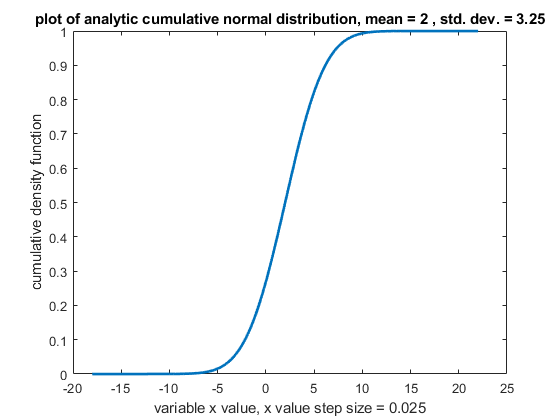

normal_cdf = normcdf(x, mu, std);
figure(2)
plot(x,normal_cdf,"LineWidth",2);
title(['plot of analytic cumulative normal distribution, mean = ' num2str(mu) ' , std. dev. = ' num2str(std) ])
ylabel('cumulative density function')
xlabel(['variable x value, x value step size = ' num2str(xstep)])

Often, probabilities in statistics are converted to "sigma" values. The sigma value is converted to a probability by integrating from negative infinity to that sigma value from the mean. This means a sigma value corresponds to the probability that a point sampled from a normal distribution with standard deviation of one and mean of zero is at most equal to that sigma value. You can also construct sigma values that are the inverse of this (the probability that the value is at least equal to the sigma value) or even double sided sigmas (the probability that the value is at least as far from the mean as the sigma value). Below we verify for the  that our integal method matches the initial listed definition. We can check that our CDF function works by checking several of the well known sigma values and comparing them to a z-table. For sigma values of 1,2, and 3, the corresponding probability values are 0.8413, 0.9772, and .99865 ,  according the wikipedia page (https://en.wikipedia.org/wiki/Standard_normal_table) . 

xvals = [mu + std,mu + 2*std, mu + 3*std] ;
cdf_vals = normcdf(xvals, mu, std)

cdf_vals =     0.8413    0.9772    0.9987


Seeing agreement between our CDF and the Z-table, we proceed. We can also look at the inverse of this question: given a probability that a value less than or equal to a given value is pulled from a distribution, what is the corresponding sigma value? We can use the built in function norminv in matlab to check that the probability values we calculated for various sigma above, do in fact refer to the correct sigma value.

norminv(cdf_vals)

ans =     1.0000    2.0000    3.0000


None of these had minus signs, but if they did, it would come from the probability being less than 0.5. This would require integrating from negative infinity to the left of the mean of a normal distribution with mean zero and standard deviation 1. 

Section 2 - The Lognormal Distribution

A similar distribtuion to the Normal distribtuion is the lognormal distribution. It often arises when the measured value is the product of many independent random variables and has a PDF of the form: $P(x) = \frac{1}{Sx \sqrt{2 \pi}} \exp \left[ -\frac{( \ln x-M)^2}{2 S^2} \right]$. Below we will look at a random sample pulled from this distribution and compare it to the analytic distribution on a log scale. 

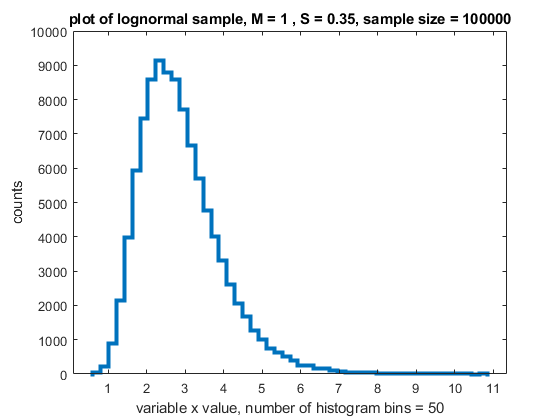

lognorm_M = 1;
lognorm_S = 0.35;
figure(3)
hist_bins = 50;
logn_sample_size = 100000;
lognorm_sample = random('LogNormal', lognorm_M, lognorm_S, [1,logn_sample_size]);
histogram(lognorm_sample, hist_bins,'DisplayStyle',"stairs",'LineWidth',3);
title(['plot of lognormal sample, M = ' num2str(lognorm_M) ' , S = ' num2str(lognorm_S) ', sample size = ' num2str(logn_sample_size)])
ylabel('counts')
xlabel(['variable x value, number of histogram bins = ' num2str(hist_bins)])

Comparing the sampled distribution histogram to the analytic form, we can check for a better fit using a log scale for the probability value. This allows us to compare them in the long tail. 

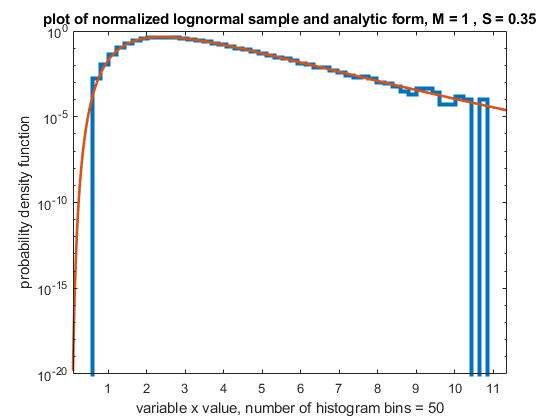

figure(4)

histogram(lognorm_sample,hist_bins,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on 
xl = xlim;
x = linspace(xl(1),xl(2),1000);
lognorm_pd = makedist("LogNormal","mu",lognorm_M,"sigma",lognorm_S);
set(gca,'YScale','log')
title(['plot of normalized lognormal sample and analytic form, M = ' num2str(lognorm_M) ' , S = ' num2str(lognorm_S) ])
ylabel('probability density function')

xlabel(['variable x value, number of histogram bins = ' num2str(hist_bins)])
plot(x,pdf(lognorm_pd,x),"LineWidth",2);

Section 3 - The Lognormal distribution and sigma values

Let's consider an example situation using a sigma value and the lognormal distribution. Suppose our background (or signal-free data) follows a lognormal distribution with $M = 3$ and $S = 0.2$. We have measured a data point of $d$ and wish to calculate the probability that we would measure a data point of this value or greater from the assumed background distribution. We can also find the corresponding sigma value. To do so, we can integrate the lognormal distribution over all values less than $d$, giving the probability that the data point is from the background of 1 minus that: $1 - \int_{-\infty}^{d} dz \frac{1}{(0.2z) \sqrt{2 \pi}} \exp \left[ -\frac{( \ln z-3)^2}{2 (0.2)^2} \right]$. We use the logncdf() function built into matlab which integrates from 0 to a given value. We demonstrate for a single d value of 23. 

M = 3;
S = 0.2;
d = 23;
prob_value_background = 1 - (logncdf(d, M, S) - logncdf(-inf, M, S))

prob_value_background = 0.2491

We again use norminv() to calculate the sigma value. Here we have listed the sigma value for the probability that a data point collected fromt the background distribution is greater than or equal to the value found. Thus as the probability of that becomes smaller, the sigma value increases. 

sigma_val_logn = norminv(1 - prob_value_background)

sigma_val_logn = 0.6775

Section 4 - The Lognormal distribution and sigma values (extended)

Unlike the normal distribution, the lognormal distribution is asymmetric. So while a sigma value of zero still occurs when the data point lies on the mean, the rate of change of the sigma value on the left and right side is different. Namely, it drops faster to the left of the mean:

M = 3;
S = 0.2;
d = [exp(3) + 5, exp(3) + 10, exp(3) + exp(3)];
prob_value_background = 1 - (logncdf(d, M, S) - logncdf(-inf, M, S));
sigma_val_logn = norminv(1 - prob_value_background)

sigma_val_logn =     1.1115    2.0202    3.4657


d = [exp(3) - 5, exp(3) - 10, exp(3) - exp(3)];
prob_value_background = 1 - (logncdf(d, M, S) - logncdf(-inf, M, S));
sigma_val_logn = norminv(1 - prob_value_background)

sigma_val_logn =    -1.4313   -3.4445      -Inf


Section 5 - The Poisson Distribution

The poisson is a discrete probability distribution that is described by a single parameter. It arises from taking the limit of a binomial distribution with fixed mean and large sample size. It can be seen in a physical setting by observing the number of photons detected in a particular time interval from a laser source.  For a mean of $\nu$ it has a PDF of the form: $P(n) = \frac{\nu^n \times e^{-\nu}}{n!}$. Below I have the analytic form overlayed with a randomly generated data set pulled from the analytic form on log y axes:

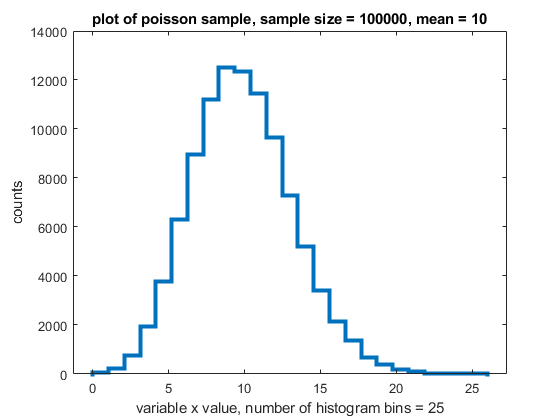

poisson_mean = 10;
figure(5)
poisson_sample_size = 100000;
poisson_sample = poissrnd(poisson_mean, [1,poisson_sample_size]);
poisson_hist_bins = max(poisson_sample(:)) - 1;
poisson_pd = makedist("Poisson","lambda",poisson_mean);
h = histogram(poisson_sample, poisson_hist_bins, 'DisplayStyle',"stairs",'LineWidth',3);

title(['plot of poisson sample, sample size = ' num2str(poisson_sample_size) ', mean = ' num2str(poisson_mean) ])
ylabel('counts')
xlabel(['variable x value, number of histogram bins = ' num2str(poisson_hist_bins)])

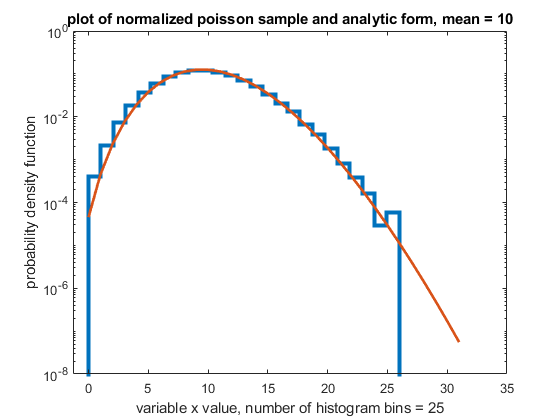



figure(6)

histogram(poisson_sample,poisson_hist_bins,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on 
xl = xlim;
% we include a region of the analytic pdf past the sample to show that in
% the sample, no measurements larger than a certain point were found
x = 0:max(poisson_sample)+5;
poisson_pd = makedist("Poisson","lambda", poisson_mean);
plot(x,pdf(poisson_pd,x),"LineWidth",2);
set(gca,'YScale','log')
drawnow
title(['plot of normalized poisson sample and analytic form, mean = ' num2str(poisson_mean) ])
ylabel('probability density function')

xlabel(['variable x value, number of histogram bins = ' num2str(poisson_hist_bins)])

Lets say we are collecting fluorescence from a single emitter in a diamond sample. Assume when there is no magnetic field present at the location of the emitter, we collect an average of 25 photons per 4 ms time interval. Assume theory tells us that as the magnetic field increases at the location of the emitter, the number of photons decreases. For a data point we measure 7 photons. We want to calculate the probability (and corresponding sigma value) for measuring 7 or fewer photons in a time interval of 4 ms. We can do this by summing the probability of measuring 0 through 7:

n_photons = 7;
% we select the range of x to include values much larger than the mean to
% accurately evaluate probability values. Because pdf() normalizes to 1, we
% need to make sure to include the majority of the probability space in the
% region
x = 0:5*poisson_mean;
poisson_pdf = pdf(poisson_pd,x);
prob_atmost_n = sum(poisson_pdf(1:n_photons+1))

prob_atmost_n = 0.2202

Again using norminv(), we can calculate a sigma value of the above probability. Note that we evaluate norminv() on 1 minus that probability so that as the probability of measuring that number of photons decreases, the sigma value increases:

poisson_sigma_val = norminv(1 - prob_atmost_n)

poisson_sigma_val = 0.7714

Because this distribution is discrete, so are the probabilites and sigma values. Because of this it is possible to sample the distribution many times and miss parts of it. For example, we could take a sample with too few repetitions and get a distribution that is has no data points for a given count number (shown below):

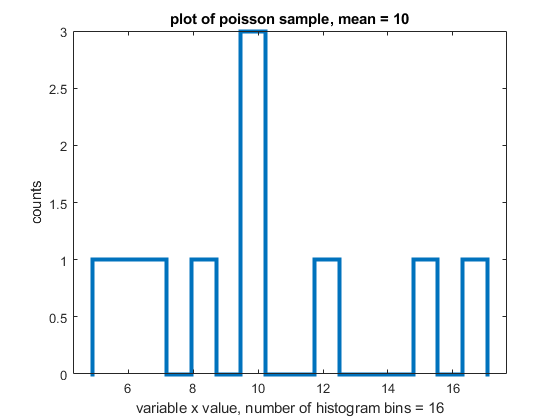

poisson_mean = 10;
figure(5)
poisson_sample_size = 10;
poisson_sample = poissrnd(poisson_mean, [1,poisson_sample_size]);
poisson_hist_bins = max(poisson_sample(:)) - 1;
poisson_pd = makedist("Poisson","lambda",poisson_mean);
h = histogram(poisson_sample, poisson_hist_bins, 'DisplayStyle',"stairs",'LineWidth',3);

title(['plot of poisson sample, mean = ' num2str(poisson_mean) ])
ylabel('counts')
xlabel(['variable x value, number of histogram bins = ' num2str(poisson_hist_bins)])

With too few measurements, we can't tell the shape of this distribution well at all! Because of the discrete nature, many underlying distributions could create this sample with so few data points. This can lead to difficulties in calculating the mean for the poisson distribution (or for other multi-parameter distributions issues in fitting them all correctly simulataneously). 

While the results of a sample are discrete, the distribtuion paramters are not necessarily. This makes sense because the mean of a set of whole numbers is not required to be a whole number. While each data point is a discrete number, the parameters that best describe a population of these discrete numbers do not have to be discrete, and can vary continuously.